Train simple models

- Load the data

iris=readtable('fisheriris.csv');

2. **From Apps, Machine Learning group, click Classification learner.**

3. On the Classification Learner tab, in the FIle section, click New Session

4. In the New Session dialog box, select the table iris from the workspace list. Analyse the data.

5. Click Start Session - this will work with the default validation scheme - cross validation.

6. From scatter plot, analyse which variables are useful for predicting the response. Select different options for X and Y.

Observation: setosa species is easy to separate from the other two species 

7. In ModelType section click the down arrow to expand the gallery and choose the model ......

8. Examine the scatter plot. An X indicates misclassified points. The blue points (`setosa` species) are all correctly classified, but some of the other two species are misclassified. Under **Plot**, switch between the **Data** and **Model Predictions** options. Observe the color of the incorrect (X) points. Alternatively, while plotting model predictions, to view only the incorrect points, clear the **Correct** check box.

9. Check the next steps in [https://www.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html](https://www.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html) and try to follow them . 

...

- Visualize the decision tree model (use the name of teh exported model)

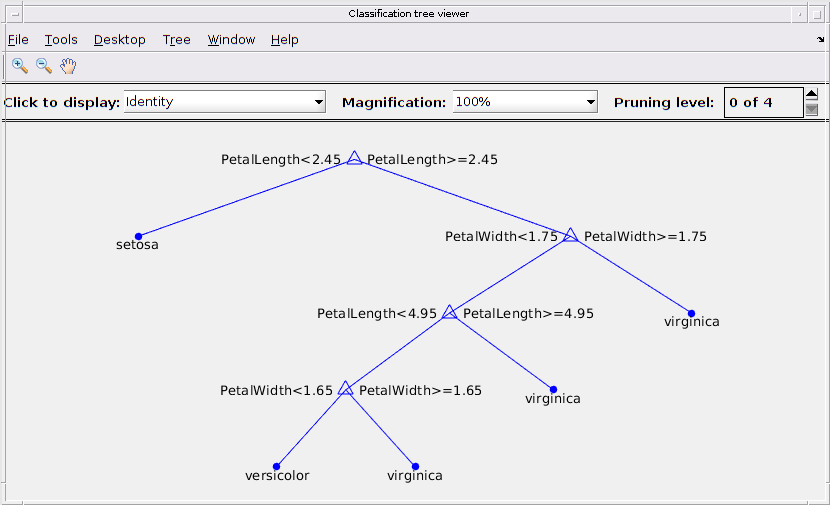

view(iris_model.ClassificationTree, 'Mode', 'graph')

- Use the model to predict

yfit = iris_model.predictFcn(iris)

yfit = 150×1 cell array
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'v

- Create a table with your data

SepalLength=[2; 1];
SepalWidth=[1.2; 2];
PetalLength=[4; 1];
PetalWidth=[1;0.2];
Species=['u';'u'];
test=table(SepalLength, SepalWidth, PetalLength, PetalWidth, Species)

test = 2×5 table
    SepalLength    SepalWidth    PetalLength    PetalWidth    Species
    ___________    __________    ___________    __________    _______

         2            1.2             4              1           u   
         1              2             1            0.2           u   


- Predict the iris species on these data

yfit = iris_model.predictFcn(test)

yfit = 2×1 cell array
    {'versicolor'}
    {'setosa'    }
